# EEG preprocessing in MATLAB

This project prepares a continuous EEG recording for later analysis. It reduces the sampling rate, attenuates line noise and slow drift, screens poorly correlated channels, and applies an average reference. MATLAB and Signal Processing Toolbox are required.

clear; clc; close all;

% Run from this project's folder, with your authorized input in data/.
inputFile = fullfile('data', 'raw_witness2.mat');
outputFile = fullfile('data', 'Task1_clean.mat');
newRate = 128;
notchBand = [48 52];
passBand = [0.5 45];
threshold = 0.4;

## 1. Read the recording and inspect Pz

EEG rows represent channels and columns represent time samples. Removing each row's temporal mean removes its constant offset. Search for Pz by name because channel order can differ between recordings.

if ~isfile(inputFile)
    error('Restricted data file "%s" is not included in this repository. Place raw_witness2.mat in the data/ folder to run.', inputFile);
end
load(inputFile, 'data', 'srate', 'chanlabels', 'pos', 'event_sample', 'suspect');
srate = double(srate);
data = double(data);
labels = chanlabels;
events = double(event_sample);  % Keep integer-valued indices in a double array
channelOffset = mean(data, 2);
data = data - channelOffset;

pzRow = find(strcmp(labels, 'Pz'));
if numel(pzRow) ~= 1
    error('The recording must contain exactly one channel named Pz.');
end
fprintf('Input size: %d channels by %d samples; sampling rate: %.0f Hz\n', ...
    size(data,1), size(data,2), srate);

Input size: 30 channels by 93400 samples; sampling rate: 200 Hz


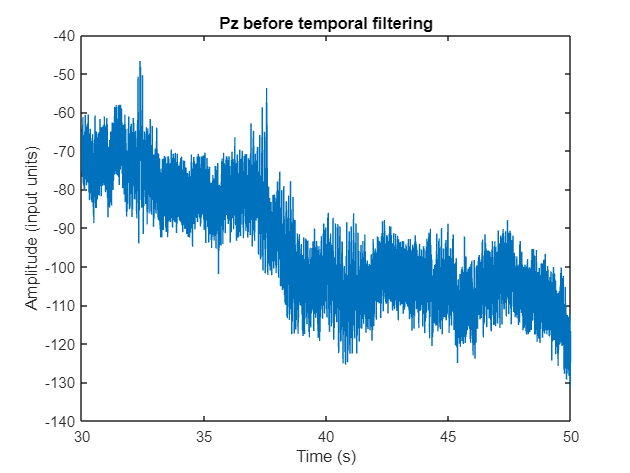

timeRaw = (0:size(data,2)-1)/srate;
figure;
plot(timeRaw, data(pzRow,:));
xlim([30 50]); xlabel('Time (s)'); ylabel('Amplitude (input units)');
title('Pz before temporal filtering');

## 2. Reduce the sampling rate and align the event indices

resample processes columns. Transpose so that each channel is a column, then restore the channels-by-samples layout. Resampling includes anti-aliasing. Apply the same rate ratio to events and round to whole-number indices.

oldRate = srate;
rateRatio = newRate/oldRate;
[p, q] = rat(rateRatio);
samplesByChannels = data.';
data = resample(samplesByChannels, p, q).';
events = round((events - 1) * rateRatio) + 1;
srate = newRate;
time = (0:size(data,2)-1)/srate;
fprintf('Resampled size: %d channels by %d samples\n', size(data,1), size(data,2));

Resampled size: 30 channels by 59776 samples


## 3. Check the spectrum and attenuate power-line interference

Estimate Pz's power spectrum before choosing a notch band. The configured 48-52 Hz stopband targets interference near 50 Hz; change it only after inspecting the spectrum. filtfilt avoids net phase delay.

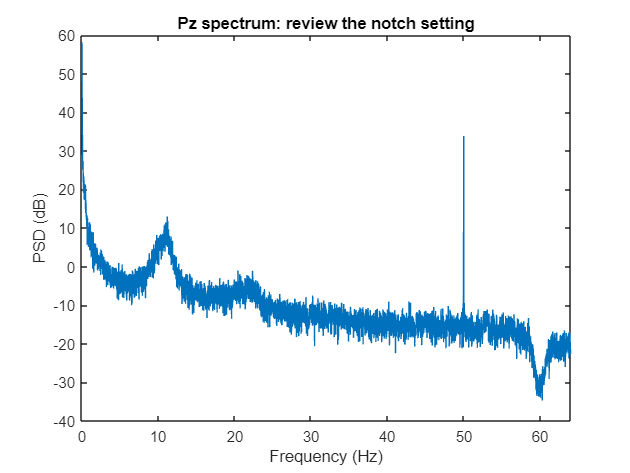

[powerBefore, frequency] = pwelch(data(pzRow,:), [], [], [], srate);
figure;
plot(frequency, 10*log10(powerBefore));
xlim([0 srate/2]); xlabel('Frequency (Hz)'); ylabel('PSD (dB)');
title('Pz spectrum: review the notch setting');

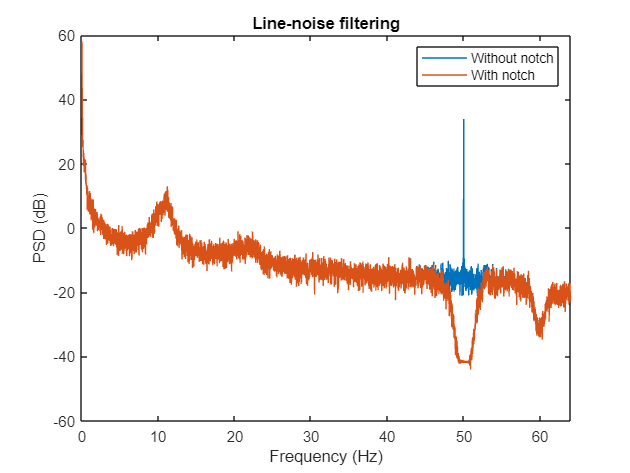


nyquist = srate/2;
[notchB, notchA] = butter(2, notchBand/nyquist, 'stop');
notchData = filtfilt(notchB, notchA, data.').';
[powerAfter, frequency] = pwelch(notchData(pzRow,:), [], [], [], srate);
figure;
plot(frequency, 10*log10([powerBefore powerAfter]));
xlim([0 nyquist]); xlabel('Frequency (Hz)'); ylabel('PSD (dB)');
legend('Without notch','With notch'); title('Line-noise filtering');

data = notchData;

## 4. Limit the temporal frequency range (Band Pass Filter)

First attenuate slow drift below 0.5 Hz, then high-frequency activity above 45 Hz. The filters have gradual transitions, not perfectly sharp cutoffs. Forward-backward filtering is offline and can produce edge transients.

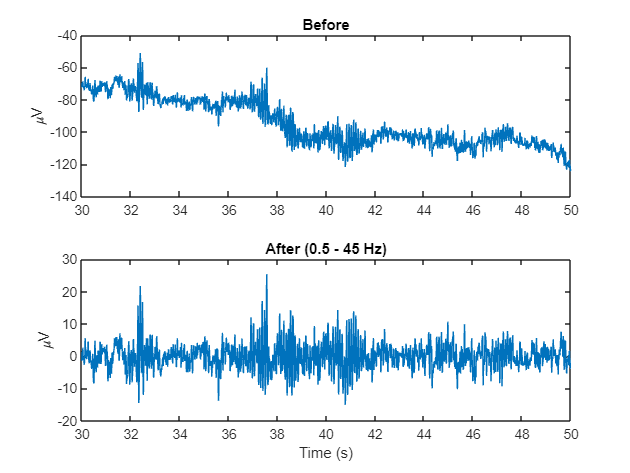

[highB, highA] = butter(2, passBand(1)/nyquist, 'high');
[lowB, lowA] = butter(4, passBand(2)/nyquist, 'low');
filteredData = filtfilt(highB, highA, data.').';
filteredData = filtfilt(lowB, lowA, filteredData.').';

figure;

subplot(2,1,1);
plot(time, data(pzRow,:));
xlim([30 50]);
title('Before');
ylabel('\muV');

subplot(2,1,2);
plot(time, filteredData(pzRow,:));
xlim([30 50]);
title('After (0.5 - 45 Hz)');
xlabel('Time (s)');
ylabel('\muV');

data = filteredData;

## 5. Review channel similarity and keep the accepted channels

Each channel's score is its strongest absolute correlation with another channel. Ignore self-correlations. A low score flags a channel for review; 0.4 is a recording-specific threshold, not a universal quality standard. Keep the same rows in the signal, channel labels, and position array.

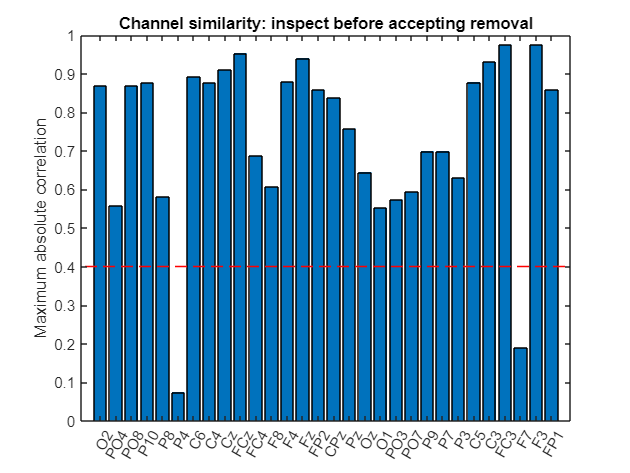

channelCorrelation = abs(corrcoef(data.'));
if any(~isfinite(channelCorrelation(:)))
    error('Undefined correlations: inspect constant or invalid channels first.');
end
numberOfChannels = size(data,1);
channelCorrelation(1:numberOfChannels+1:end) = 0;
bestMatch = max(channelCorrelation, [], 2);
keepChannel = bestMatch >= threshold;

figure;
bar(bestMatch); hold on;
plot([0 numberOfChannels+1], threshold*[1 1], 'r--');
set(gca, 'XTick', 1:numberOfChannels, 'XTickLabel', labels);
xtickangle(60); ylabel('Maximum absolute correlation');
title('Channel similarity: inspect before accepting removal');


if nnz(keepChannel) < 2
    error('Too few channels remain. Review the threshold and input signals.');
end
if all(keepChannel)
    fprintf('No channels were flagged by this threshold.\n');
else
    fprintf('Flagged channels: %s\n', strjoin(labels(~keepChannel), ', '));
end

Flagged channels: P4, F7


fprintf('Lowest retained score: %.4f\n', min(bestMatch(keepChannel)));

Lowest retained score: 0.5525


data = data(keepChannel,:);
labels = labels(keepChannel);
pos = pos(keepChannel,:);

## 6. Reference the retained signals to their spatial average

Compute one reference value per time sample using only retained channels. Removing poor channels first avoids including their noise in the reference. Check the largest residual channel mean rather than a single grand mean.

referenceSignal = mean(data,1);
data = data - referenceSignal;
referenceResidual = max(abs(mean(data,1)));
fprintf('Maximum absolute channel-mean residual: %.3e\n', referenceResidual);

Maximum absolute channel-mean residual: 6.293e-14


## 7. Save the signals together with their metadata

Store samples as single precision to reduce file size. Keep events as double so later epoch-offset vectors can be added without mixed-integer errors. This clean file remains restricted and must not be uploaded to GitHub.

data = single(data);
save(outputFile, 'data', 'srate', 'labels', 'pos', 'events', 'suspect');
fprintf('Saved the local output to %s\n', outputFile);

Saved the local output to data\Task1_clean.mat
